clear all;
close all;
clc;

## données du problème


L = 1; %longueur
Nx = 10; %nb points de discrétisation du domaine

alpha = 1; %coefficient dans l'EDP (par exemple la conductivité thermique)
h = 1/(Nx+1); %pas d'espace
k = 1/4*h^2/alpha; %pas de temps
pas = [];
err = [];


## schéma implicite

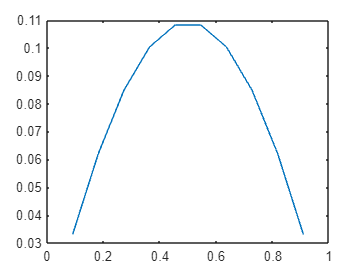

for p = 1:30
    Nx = 10*p;
    h = 1/(Nx+1);
    k = 2*h^2/alpha; %pas de temps
    pas = [pas h]; %on stocke le pas
    A = eye(Nx);
    C = 2*eye(Nx) - diag(diag(ones(Nx-1)),1) - diag(diag(ones(Nx-1)),-1);
    B = eye(Nx) + alpha*k/h^2*C; % BUn+1 = AUn + kF
    X = linspace(h,L-h,Nx); %axe abscisses pour afficher U

    % initialisation de U
    U = zeros(Nx,1);
    for i = 1:Nx
        U(i) = 1/(2*alpha)*(i*h)*(1-i*h);
    end

    Ntc = 20;
    for n = 1:Ntc
        
        %solution exp
        U = inv(B)*U;
        plot(X,U)
        Ure = [0
            U
            0];
        Xre = [0 X L];

        %solution th
        Uth = u(Xre,n*k,100,alpha);
        plot(Xre,Ure-Uth','-g') %erreur temporelle
        hold on
        
        
    end

    err = [err norm(Uth'-Ure,"inf")]; %on stocke l'erreur
end


hold off
plot(log(pas),log(err),'-r') %ordre d'espace 2